# Polynomial interpolation

Nel seguito di questo notebook verrà presentato un approccio alla base del ML: fitting polinomiale. Nello specifico verranno generati dei punti casualmente distribuiti attorno alla funzione seno e si otterà il polinomio interpolante (overfitting) che attraversa tutti i punti (di learning). In seguito si rappresenteranno polinomi aventi gradi inferiori a $n-1$ (dove $n$ rappresenta il numero di punti precedentemente generati) e si calcolerà lo scarto quadratico medio o root mean square error $E_{RMS}$ per ogni grado.

% cleaning enviroment
clc
clear

Rappresento la funzione $y = sin(2\pi x)$ con $0 \leq x\leq 1$

% funzione seno
sen = @(x) sin(2*pi*x);

% genero vettori
x = linspace(0,1,100);
y = sen(x);

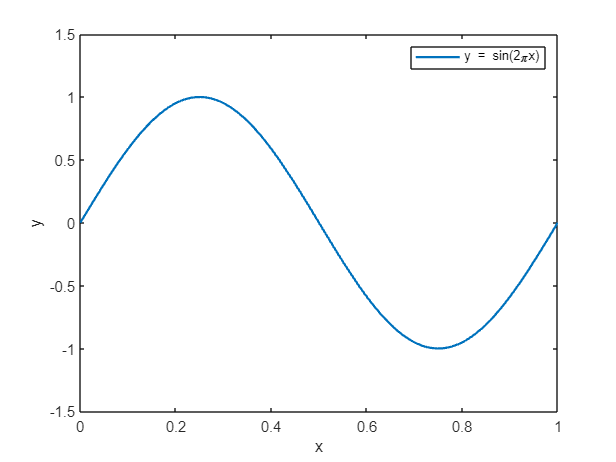

% plotto funzione seno
lw = 1.5; % plot line width
figure;
plot(x,y,"LineWidth",lw)
xlabel("x")
ylabel("y")
legend("y = sin(2\pix)")
xlim([0 1])
ylim([-1.5 1.5])

Genero set di learning avente `n_lrn` punti randomicamente distribuiti attorno alla funzione seno

% genero set di learning
n_lrn = 20;
x_lrn = linspace(0,1,n_lrn);
% rumore
eps = 0.2; 
y_lrn = sin(2*pi*x_lrn) + rand_between(-eps,eps,n_lrn)';

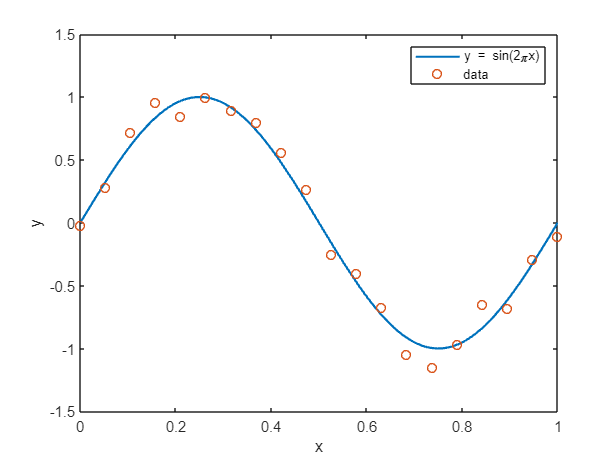

% rappresento punti
figure;
plot(x,y,"LineWidth",lw)
hold on
plot(x_lrn,y_lrn,"o","LineWidth",1)
legend("y = sin(2\pix)","data")
xlabel("x")
ylabel("y")
hold off
xlim([0 1])
ylim([-1.5 1.5])

Il **polinomio interpolante** è quel polinomio la cui curva passa attraverso tutti i punti sperimentali. Se il polinomio ha forma generale $y=a_1 + a_2 x + a_3 x^3 + ... + a_n x^{n-1}$ dove 

- $n$ è il numero di punti da fittare;

- $a_1$, $a_2$, ..., $a_n$ sono gli $n$ coefficienti del polinomio;

Posto $\bar{x} = (x_1, x_2, ..., x_n)$, affinchè il polinomio attraversi tutti i punti del vettore $\bar{x}$ deve verificare le seguenti condizioni:

- $y_1=a_1 + a_2 x_1 + a_3 x_1^3 + ... + a_n x_1^{n-1}$     (condizione passaggio per il punto $x_1$)

- $y_2=a_1 + a_2 x_2 + a_3 x_2^3 + ... + a_n x_2^{n-1}$     (condizione passaggio per il punto $x_2$)

- ...

- $y_n=a_1 + a_2 x_n + a_3 x_n^3 + ... + a_n x_n^{n-1}$     (condizione passaggio per il punto $x_n$)

che rappresenta un sistema di $n$ equazioni in $n$ incognite. Il nostro obiettivo consiste nel risolvere il sistema per determinare gli $n$ coefficienti $a_1$, $a_2$, ..., $a_n$ e quindi il polinomio interpolante.

Sfruttando il formalismo matriciale è possibile rappresentare il sistema di $n$ equazioni come di seguito

$\pmatrix{y_1 \cr y_2 \cr ... \cr y_n} = \pmatrix{1 & x_1 & x_1^2 & ... & x_1^{n-1} \cr 1 & x_2 & x_2^2 & ... & x_2^{n-1} \cr ... & ... & ... & ... & ... \cr 1 & x_n & x_n^2 & ... & x_n^{n-1}} \cdot \pmatrix{a_1 \cr a_2 \cr ... \cr a_n}$.

La matrice 


$$V=\pmatrix{1 & x_1 & x_1^2 & ... & x_1^{n-1} \cr 1 & x_2 & x_2^2 & ... & x_2^{n-1} \cr ... & ... & ... & ... & ... \cr 1 & x_n & x_n^2 & ... & x_n^{n-1}}$$


prende il nome "matrice di Vandermonde" e si genera elevando gli elementi del vettore $\bar{x}$  da 0 a $n-1$.

In MATLAB è possibile generare la matrice di Vandermonde utilizzando la funzione `vander()`

% genero matrice di Vandermonde
V = fliplr(vander(x_lrn))

V =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0000    0.0526    0.0028    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1053    0.0111    0.0012    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.1579    0.0249    0.0039    0.0006    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.0000    0.2105    0.0443    0.0093    0.0020    0.0004    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000  

% latex(sym(V))

Risolvo il sistema e determino i coefficienti $a_1$, $a_2$, ..., $a_n$ eseguendo il prodotto matriciale $V^{-1} \cdot \bar{y}$ in cui $\bar{y} = (y_1, y_2, ..., y_n)$

Alla luce della forma matriciale, è possibile determinare i coefficienti $\alpha$ eseguendo il prodotto righe per colonna tra l'inversa della matrice di Vandermonde e il vettore colonna y.

In  MATLAB è possibile eseguire questa operazione sia sfruttando la funzione `pinv()` che determina la matrice pseudoinversa

% a = pinv(V)*(y_lrn')

oppure utilizzando la sintassi `V\y_lrn'`

% determino i coefficienti
a = V\y_lrn'

a = 1.0e+13 *

   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0001
    0.0011
   -0.0086
    0.0491
   -0.2121
    0.7083



% ottengo il polinomio funzione degli scalari x e m (grado)
poly = @(x,m) (x.^(0:m))*(a(1:m+1));

Determiniamo i valori previsti

% over-fitting
% z = zeros(1,100);
% for i=1:100
%     z(i) = poly(x(i),n_lrn-1);
% end

% utilizzando la funzione poly_predict determino le ordinate previste dal
% modello
z = poly_predict(x,poly,n_lrn-1)

z =    -0.0245  172.8784  159.8665   97.3508   40.6030    5.0567  -10.8013  -13.6871  -10.2067   -5.0093   -0.6236    2.0395    3.0469    2.9047    2.1961    1.3868    0.7577    0.4166    0.3465    0.4642    0.6687    0.8742    1.0262    1.1034    1.1113    1.0714    1.0103    0.9512    0.9093    0.8895    0.8889    0.8985    0.9082    0.9086    0.8944    0.8643    0.8210    0.7697    0.7167    0.6670    0.6236    0.5864    0.5525    0.5171    0.4742    0.4189    0.3478    0.2608    0.1605    0.0527


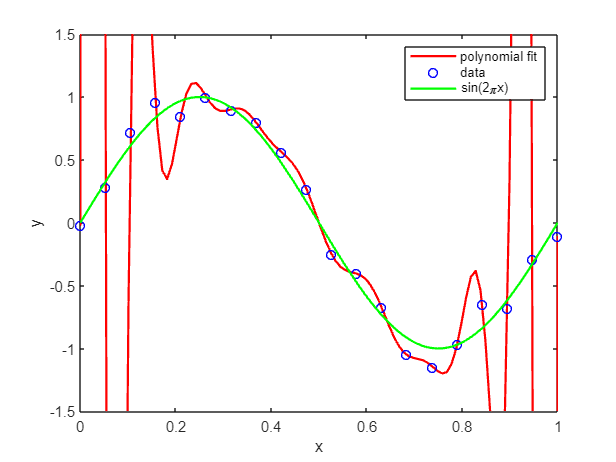

% plotting predicted values
figure;
plot(x,z,"r","LineWidth",lw)
hold on
plot(x_lrn,y_lrn,'ob',"LineWidth",1)
plot(x,y,"g","LineWidth",lw)
hold off
legend("polynomial fit", "data", "sin(2\pix)")
xlabel("x")
ylabel("y")
ylim([-1.5 1.5])
xlim([0 1])

Cosa succede utilizzando polinomi di grado inferiore a $n-1$?

V =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


a = 0.0023

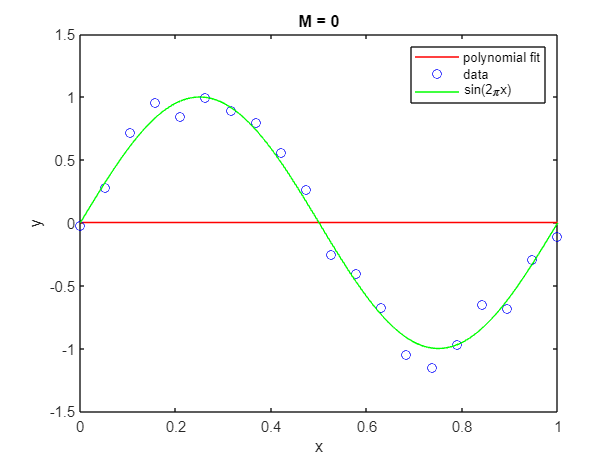

V =     1.0000         0
    1.0000    0.0526
    1.0000    0.1053
    1.0000    0.1579
    1.0000    0.2105
    1.0000    0.2632
    1.0000    0.3158
    1.0000    0.3684
    1.0000    0.4211
    1.0000    0.4737


a =     0.8363
   -1.6681


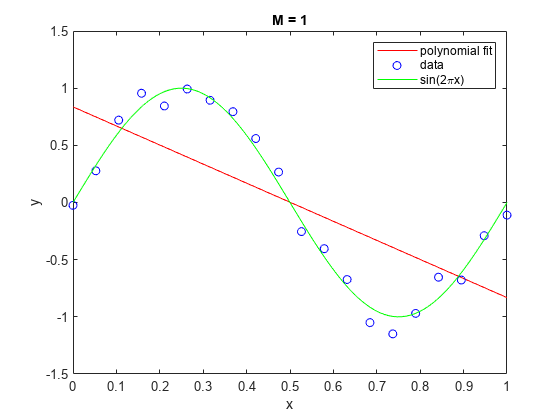

V =     1.0000         0         0
    1.0000    0.0526    0.0028
    1.0000    0.1053    0.0111
    1.0000    0.1579    0.0249
    1.0000    0.2105    0.0443
    1.0000    0.2632    0.0693
    1.0000    0.3158    0.0997
    1.0000    0.3684    0.1357
    1.0000    0.4211    0.1773
    1.0000    0.4737    0.2244


a =     0.8126
   -1.5180
   -0.1501


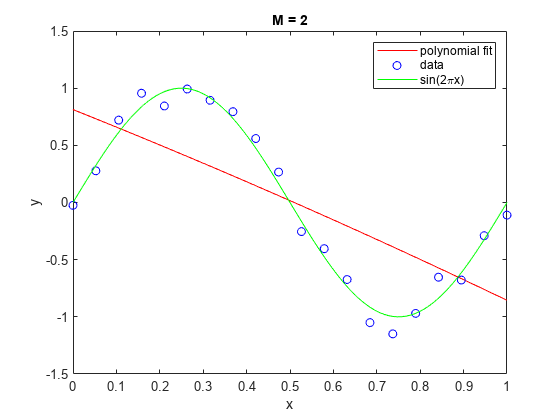

V =     1.0000         0         0         0
    1.0000    0.0526    0.0028    0.0001
    1.0000    0.1053    0.0111    0.0012
    1.0000    0.1579    0.0249    0.0039
    1.0000    0.2105    0.0443    0.0093
    1.0000    0.2632    0.0693    0.0182
    1.0000    0.3158    0.0997    0.0315
    1.0000    0.3684    0.1357    0.0500
    1.0000    0.4211    0.1773    0.0746
    1.0000    0.4737    0.2244    0.1063


a =    -0.1240
   11.4055
  -33.3006
   22.1003


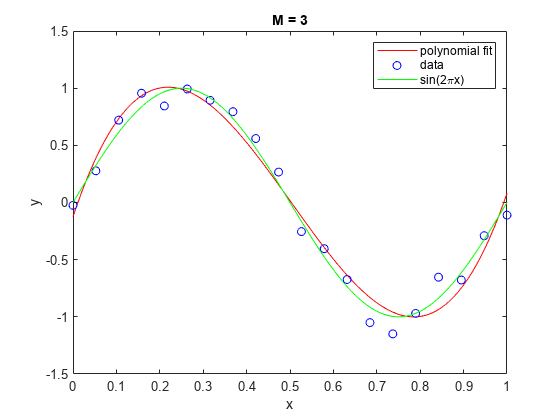

% plotting at different M (polynomial order)
for m = 0:3

    % funzione vander personalizzata che permette di costruire matrici di
    % Vandermonde incomplete in funzione del grado m fornito
    V = custom_vander(x_lrn,m)
    a = V\y_lrn'
    poly = @(x,m) (x.^(0:m))*(a(1:m+1));
    
    figure;
    plot(x,poly_predict(x,poly,m),"r")
    hold on
    plot(x_lrn,y_lrn,'ob')
    plot(x,y,"g")
    hold off
    legend("polynomial fit", "data", "sin(2\pix)")
    xlabel("x")
    ylabel("y")
    ylim([-1.5 1.5])
    xlim([0 1])
    title(sprintf("M = %d",m))
end

## Errore di learning

Per questa occasione utilizzeremo il root mean square error (o scarto quadratico medio)


$$E_{RMS} = \frac{1}{N} \sum_i^N (P_i - O_i)^2$$


dove

- $N$ rappresenta il numero di punti;

- $P_i$ il valore previsto;

- $O_i$ il valore osservato

Noi siamo interessati all'andamento di $E_{RMS}$ in funzione del grado $m$ del polinomio quindi, se il polinomio completo ha grado $M$, calcoleremo l'errore $M+1 = N$ volte

% initializing vectors
learning_error = zeros(1,n_lrn);
y_fit = learning_error;

for j = 1:n_lrn
    m = j-1;
    V = custom_vander(x_lrn,m);
    a = V\y_lrn';
    poly = @(x,m) (x.^(0:m))*(a(1:m+1));
    y_fit = poly_predict(x_lrn,poly,m);

    % calculating learning error
    learning_error(j) = sqrt(sum((y_fit-y_lrn).^2))/n_lrn;
end

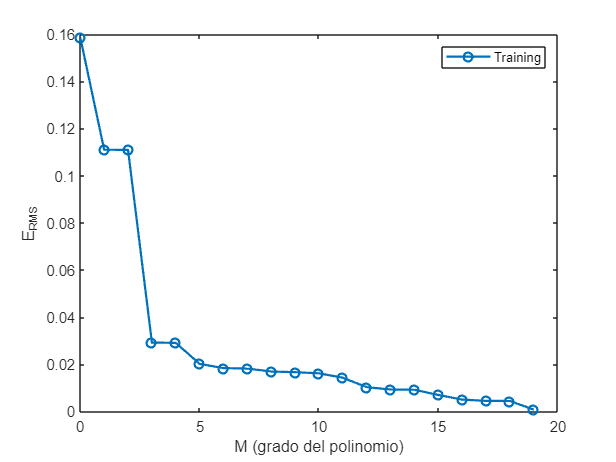

% plotting learning error
plot(0:n_lrn-1,learning_error,"-o","LineWidth",lw)
xlabel("M (grado del polinomio)")
ylabel("E_{RMS}")
legend("Training")

## Errore di testing

to do

## Funzioni

function randbet = rand_between(a,b,n)
    randbet = a + (b-a).*rand(n,1);
end

% creo funzione custom_vander
% x: vettore a partire da cui calcolare la matrice di Vandermonde arrestata
% m: grado del polinomio personalizzato
function [output_matrix] = custom_vander(x,m)
    output_matrix = zeros(1, m+1);
    for i=1:length(x)
        output_matrix(i,:) = x(i).^(0:1:m);
    end
end

% funzione poly_predict permette di ottenere le ordinate dato un polinomio P
% x: vettore
% poly: polinomio (function handle)
% m: scalare. Grado del polinomio
function output_vector = poly_predict(x,poly,m)
    lx = length(x);
    output_vector = zeros(1,lx);
    for i=1:lx
        output_vector(i) = poly(x(i),m);
    end
end